clear;
clc;

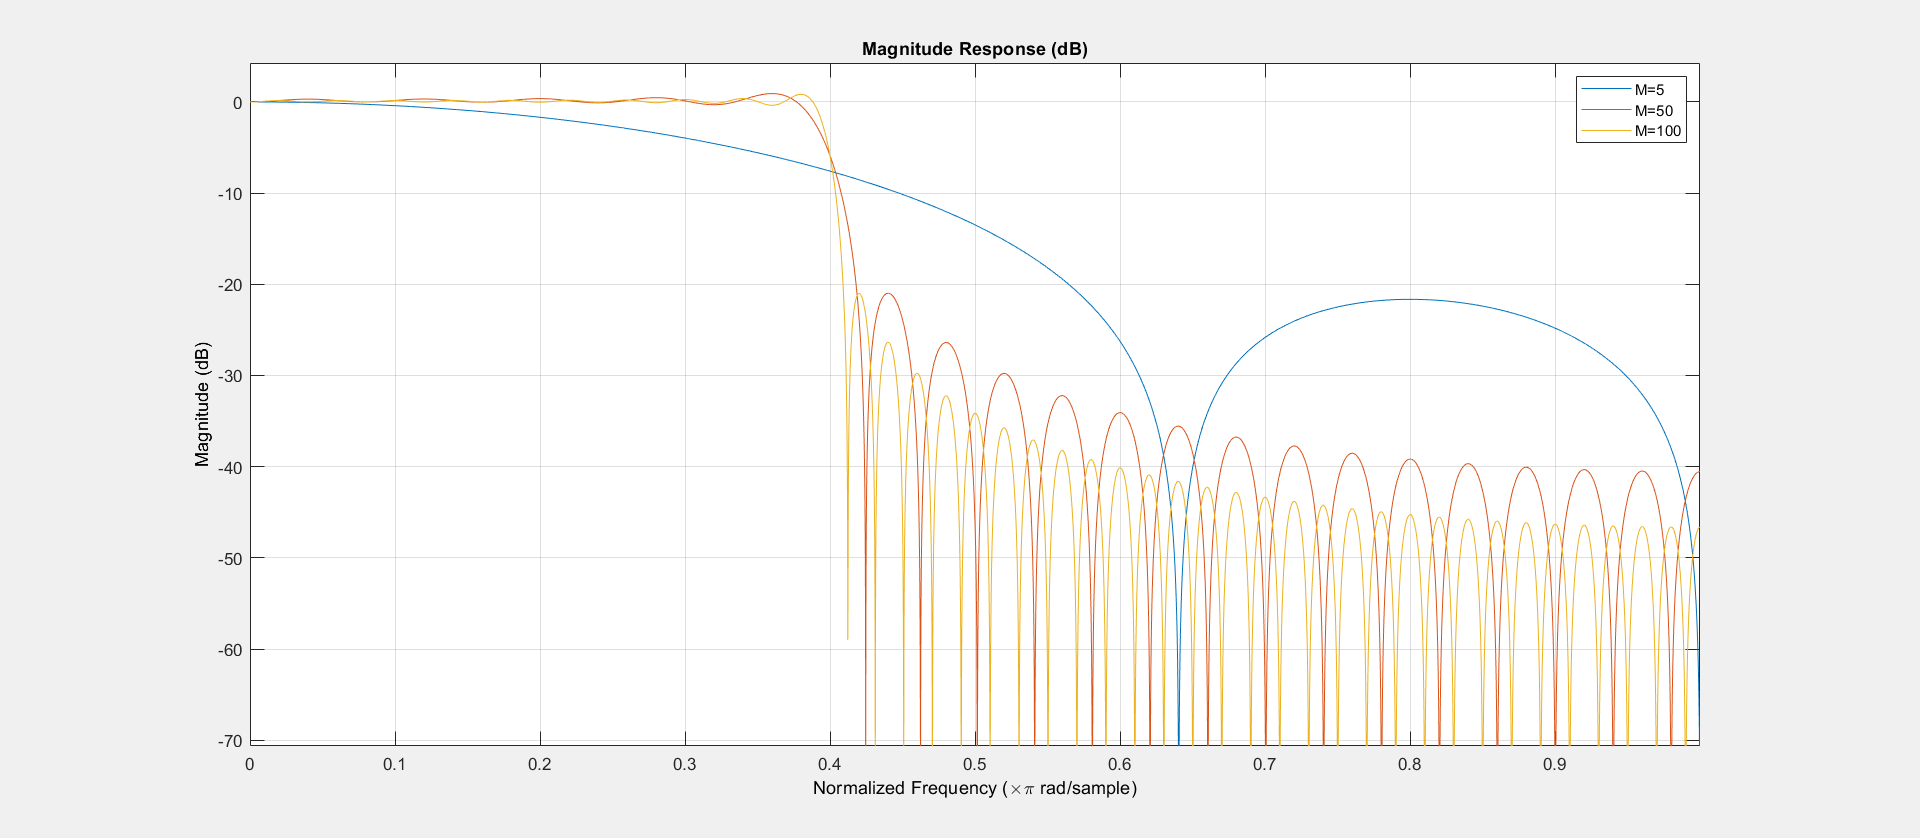

load H5.mat;
load H50.mat;
load H100.mat;
fvtool(H5,H50,H100)
legend('M=5','M=50','M=100')

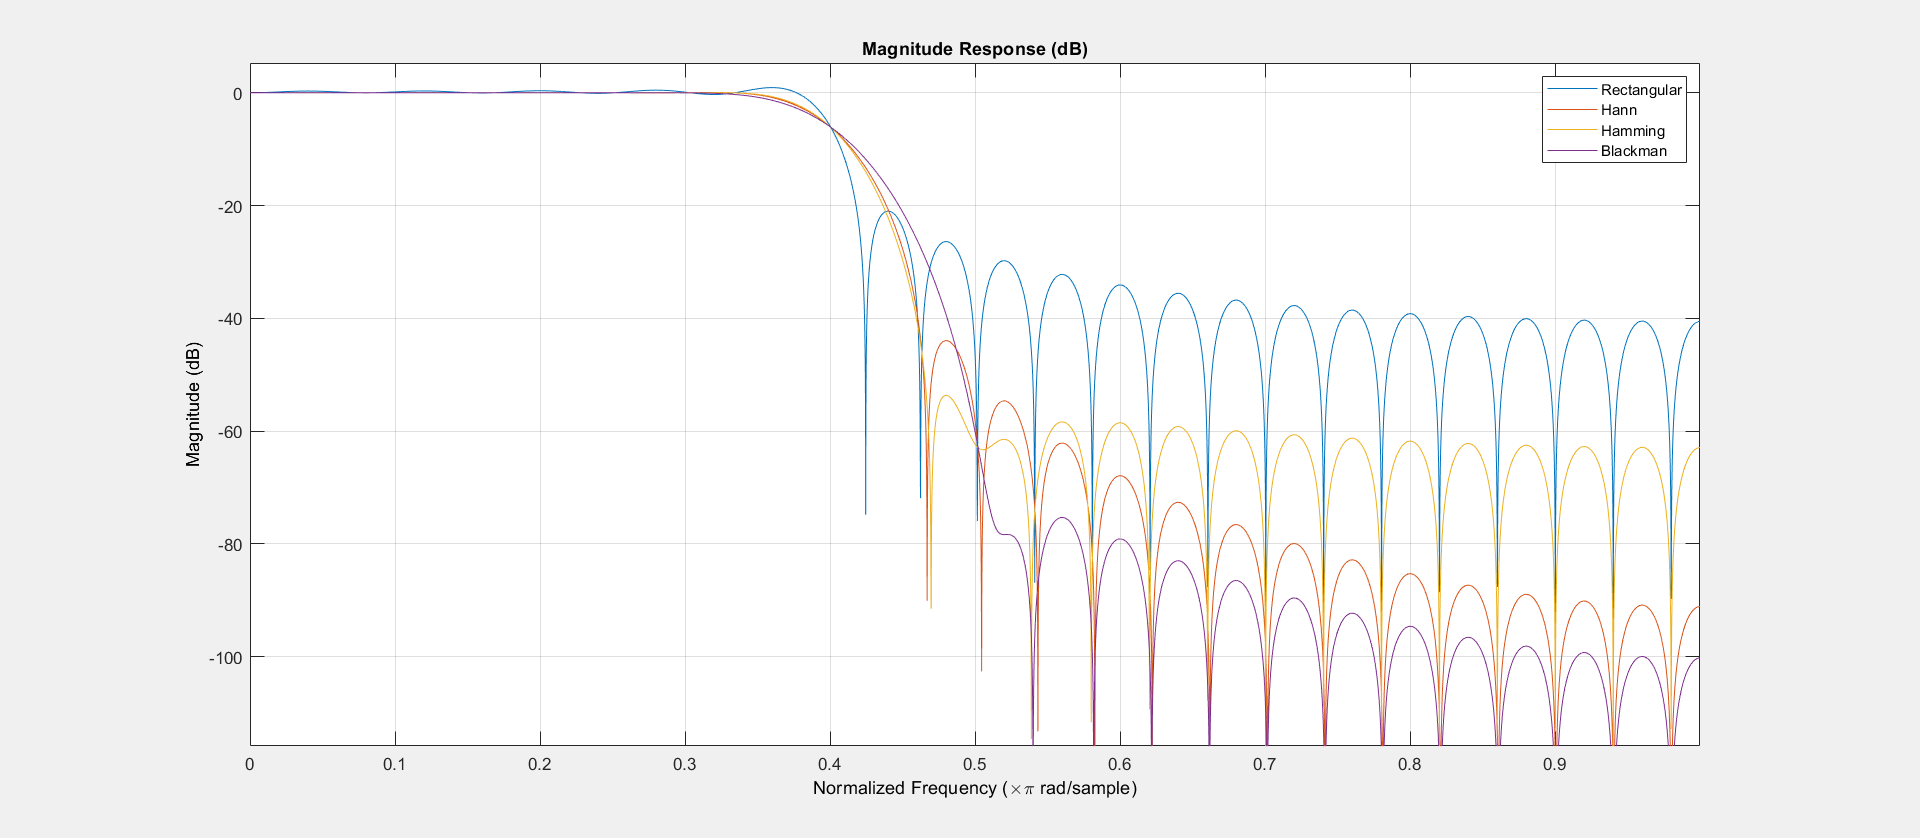

load Hamming.mat;
load Hann.mat;
load Blackman.mat;

wvt=wvtool(rectwin(50),hann(50),hamming(50),blackman(50));
legend(wvt.CurrentAxes,'Rectangular','Hann','Hamming','Blackman');
fvtool(H50,Hann, Hamming, Blackman);
legend('Rectangular','Hann','Hamming','Blackman');

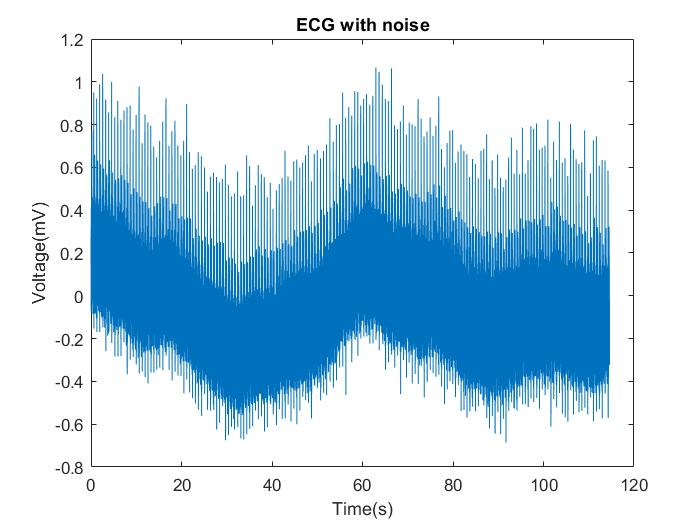

load ECG_with_noise.mat
t=(0:length(nECG)-1)/500;
plot(t,nECG)
xlabel('Time(s)')
ylabel('Voltage(mV)')
title("ECG with noise")

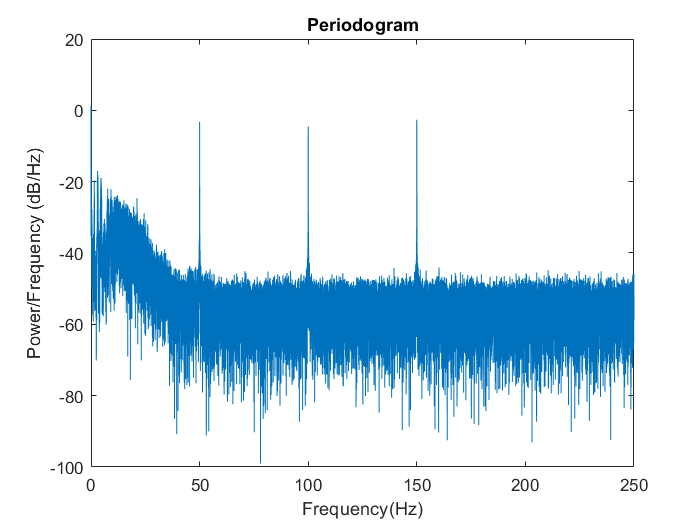


[pxx,f]=periodogram(nECG,[],[],500);
plot(f,10*log10(pxx))
title('Periodogram')
xlabel('Frequency(Hz)')
ylabel('Power/Frequency (dB/Hz)')

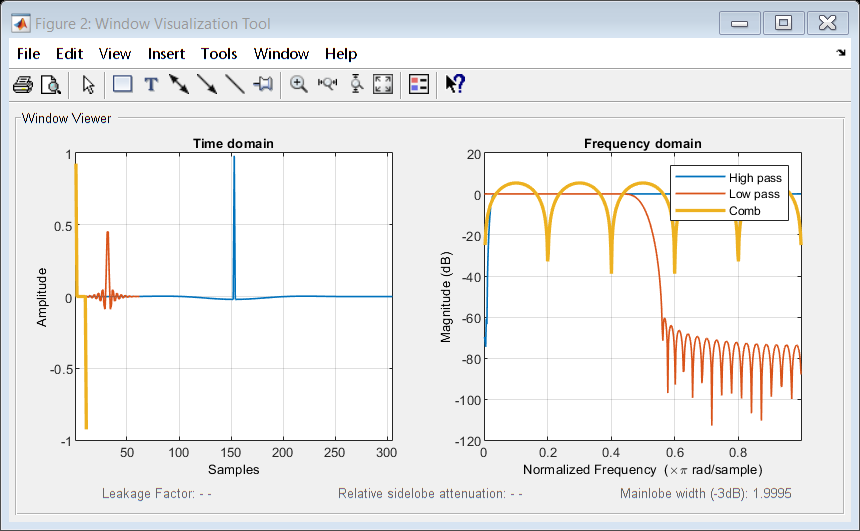

[High,high_N,high_beta]=high_pass();
[Low,Low_N,Low_beta]=low_pass();
comb_filter=comb_filt();
wvt=wvtool(High.Numerator,Low.Numerator,comb_filter.Numerator);
legend(wvt.CurrentAxes,'High pass','Low pass','Comb');

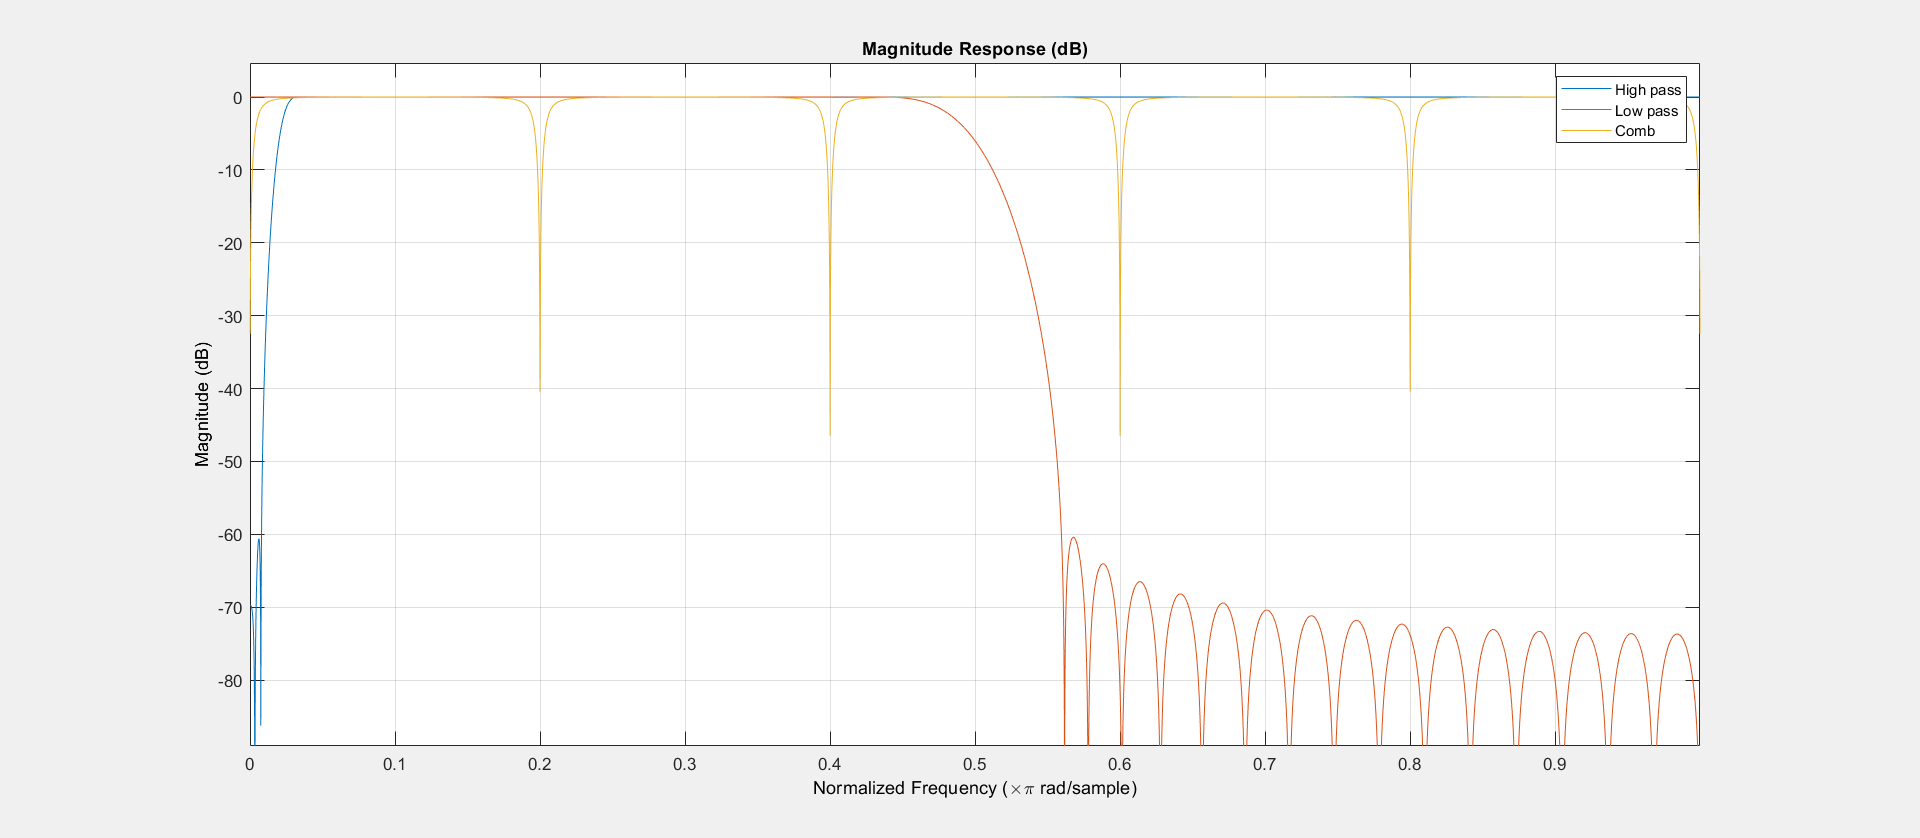

fvtool(High,Low,comb_filter);
legend('High pass','Low pass','Comb')

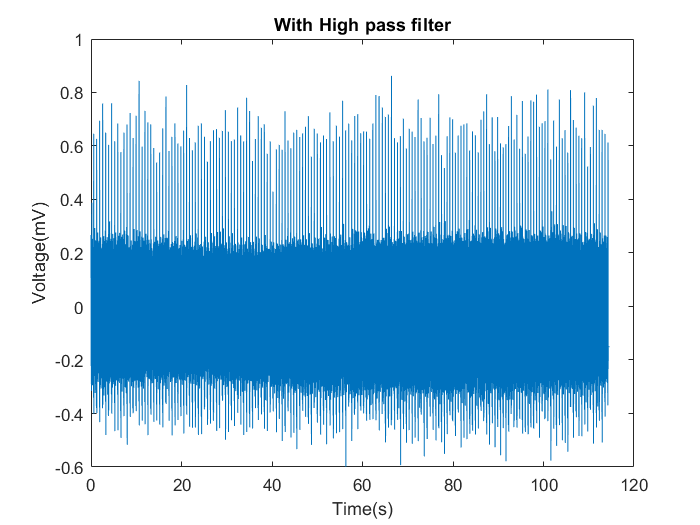

t=(0:length(nECG)-1)/500;

High_pass_filtered_ecg=filter(High,nECG);
group_delay=floor(high_N/2);
High_pass_filtered_ecg1 = [High_pass_filtered_ecg(1,group_delay+1:size(High_pass_filtered_ecg,2)),ones(1,group_delay)*High_pass_filtered_ecg(1,end)];
plot(t,High_pass_filtered_ecg1)
title('With High pass filter')
xlabel('Time(s)')
ylabel('Voltage(mV)')

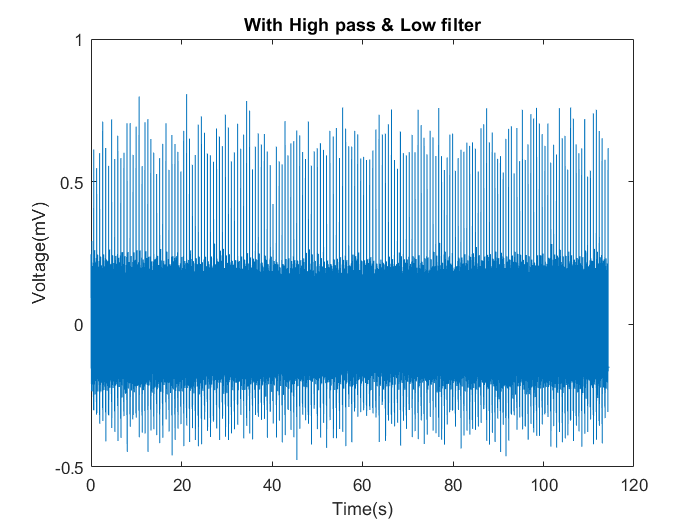


high_Low_pass_filtered_ecg=filter(Low,High_pass_filtered_ecg1);
group_delay=floor(Low_N/2);
high_Low_pass_filtered_ecg1 = [high_Low_pass_filtered_ecg(1,group_delay+1:size(high_Low_pass_filtered_ecg,2)),ones(1,group_delay)*high_Low_pass_filtered_ecg(1,end)];
plot(t,high_Low_pass_filtered_ecg1)
title('With High pass & Low filter')
xlabel('Time(s)')
ylabel('Voltage(mV)')

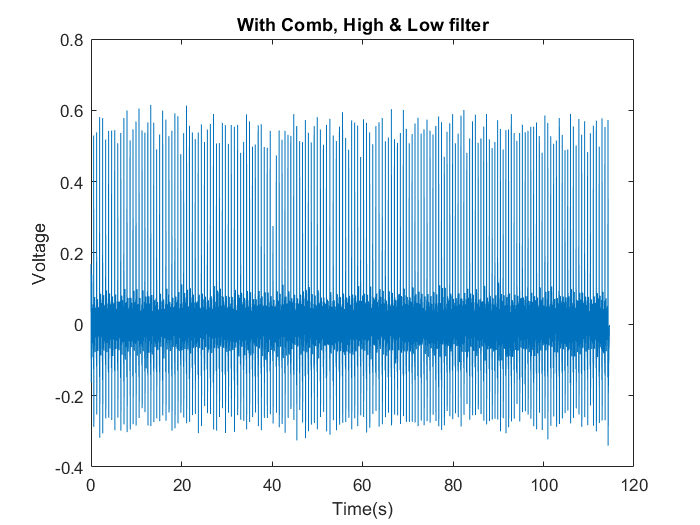


combined_filtered_ecg=filter(comb_filter,high_Low_pass_filtered_ecg1);
combined_filtered_ecg1 = [combined_filtered_ecg(1,6:size(combined_filtered_ecg,2)),ones(1,5)*combined_filtered_ecg(1,end)];
plot(t,combined_filtered_ecg1)
title('With Comb, High & Low filter')
xlabel('Time(s)')
ylabel('Voltage')

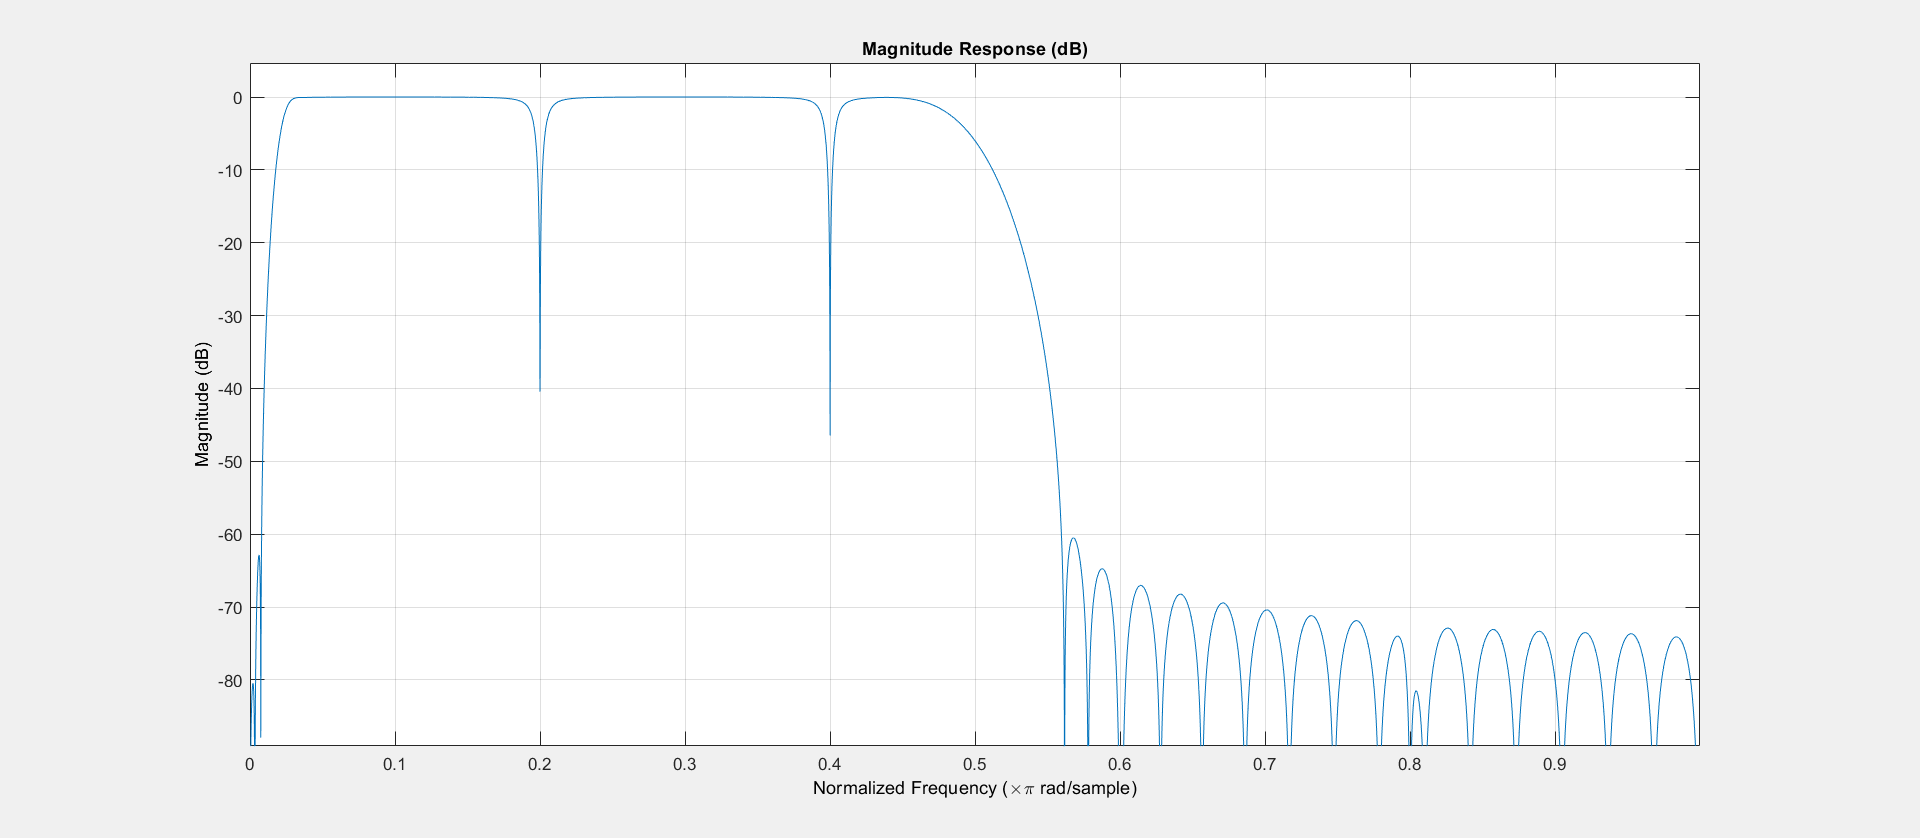

fvtool(dfilt.cascade(High,Low,comb_filter));

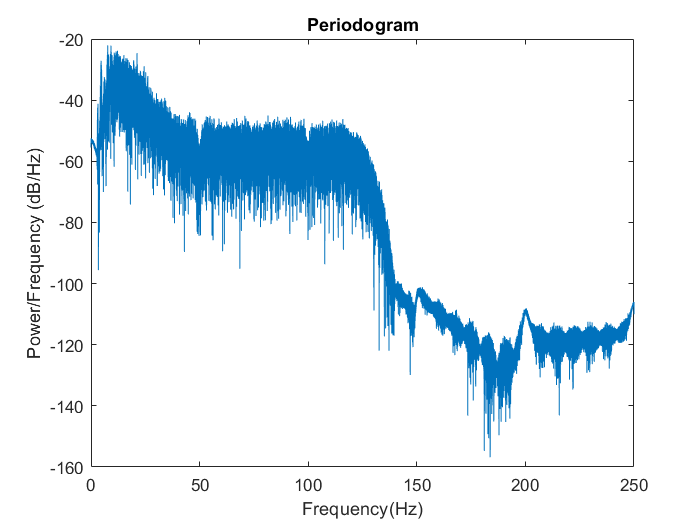

[pxx_new,f_new]=periodogram(combined_filtered_ecg1,[],[],500);
plot(f_new,10*log10(pxx_new))
title('Periodogram')
xlabel('Frequency(Hz)')
ylabel('Power/Frequency (dB/Hz)')

**Section 5**

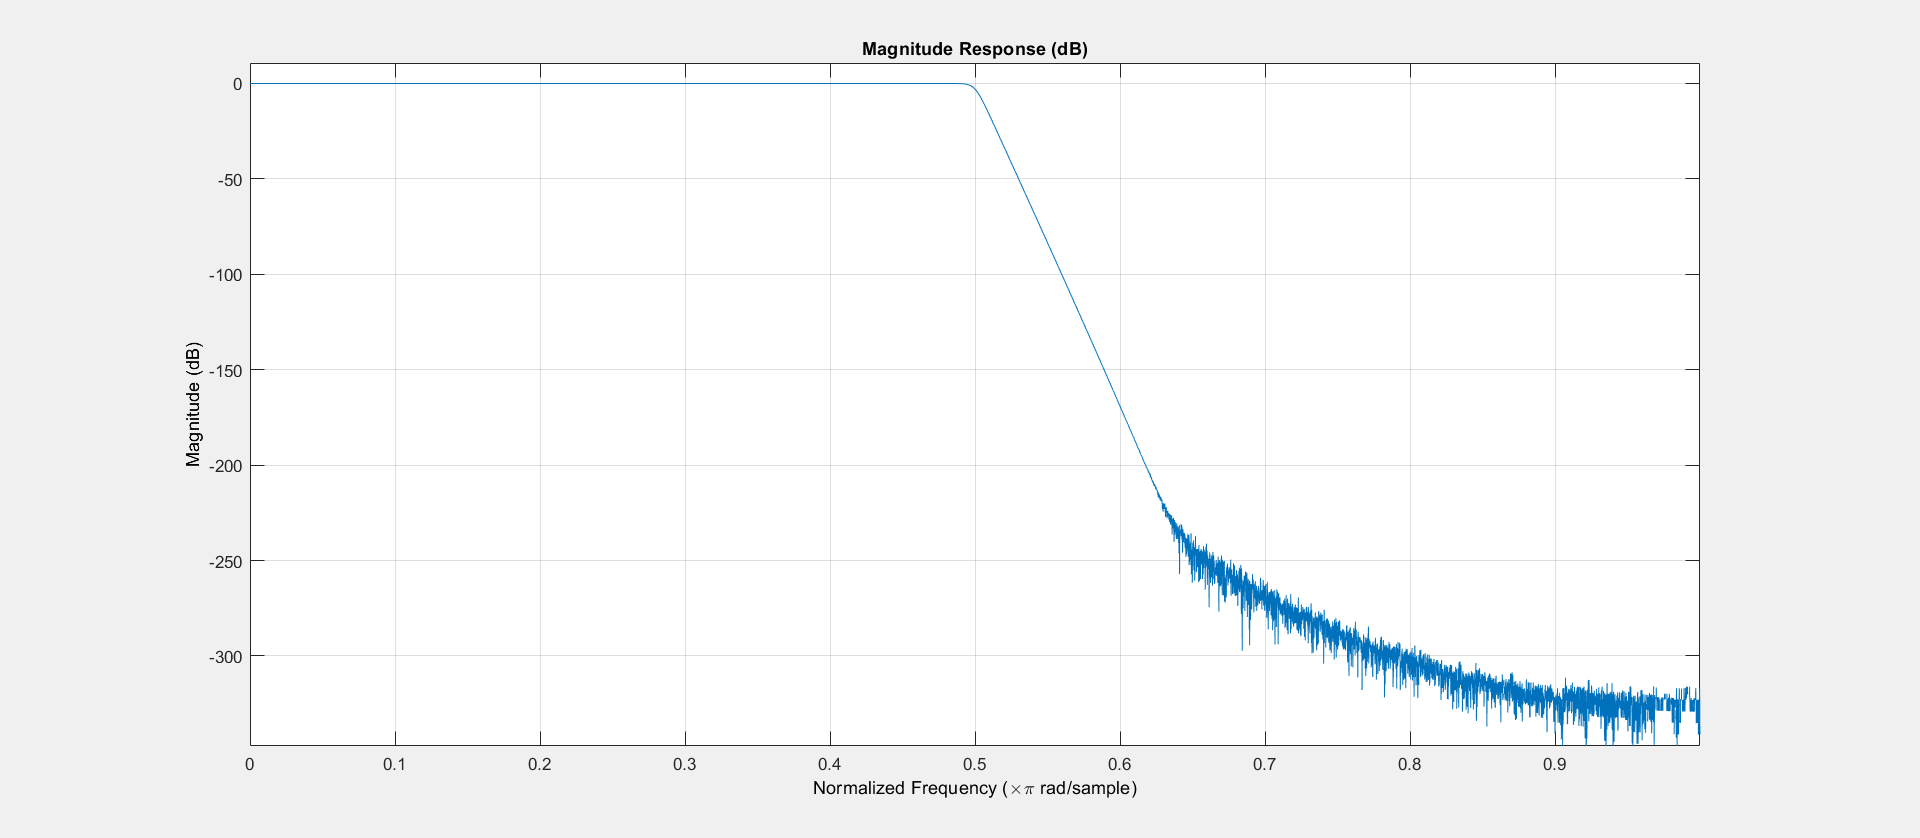

[lpb,lpa]=butter(Low_N,125/250);
fvtool(lpb,lpa)

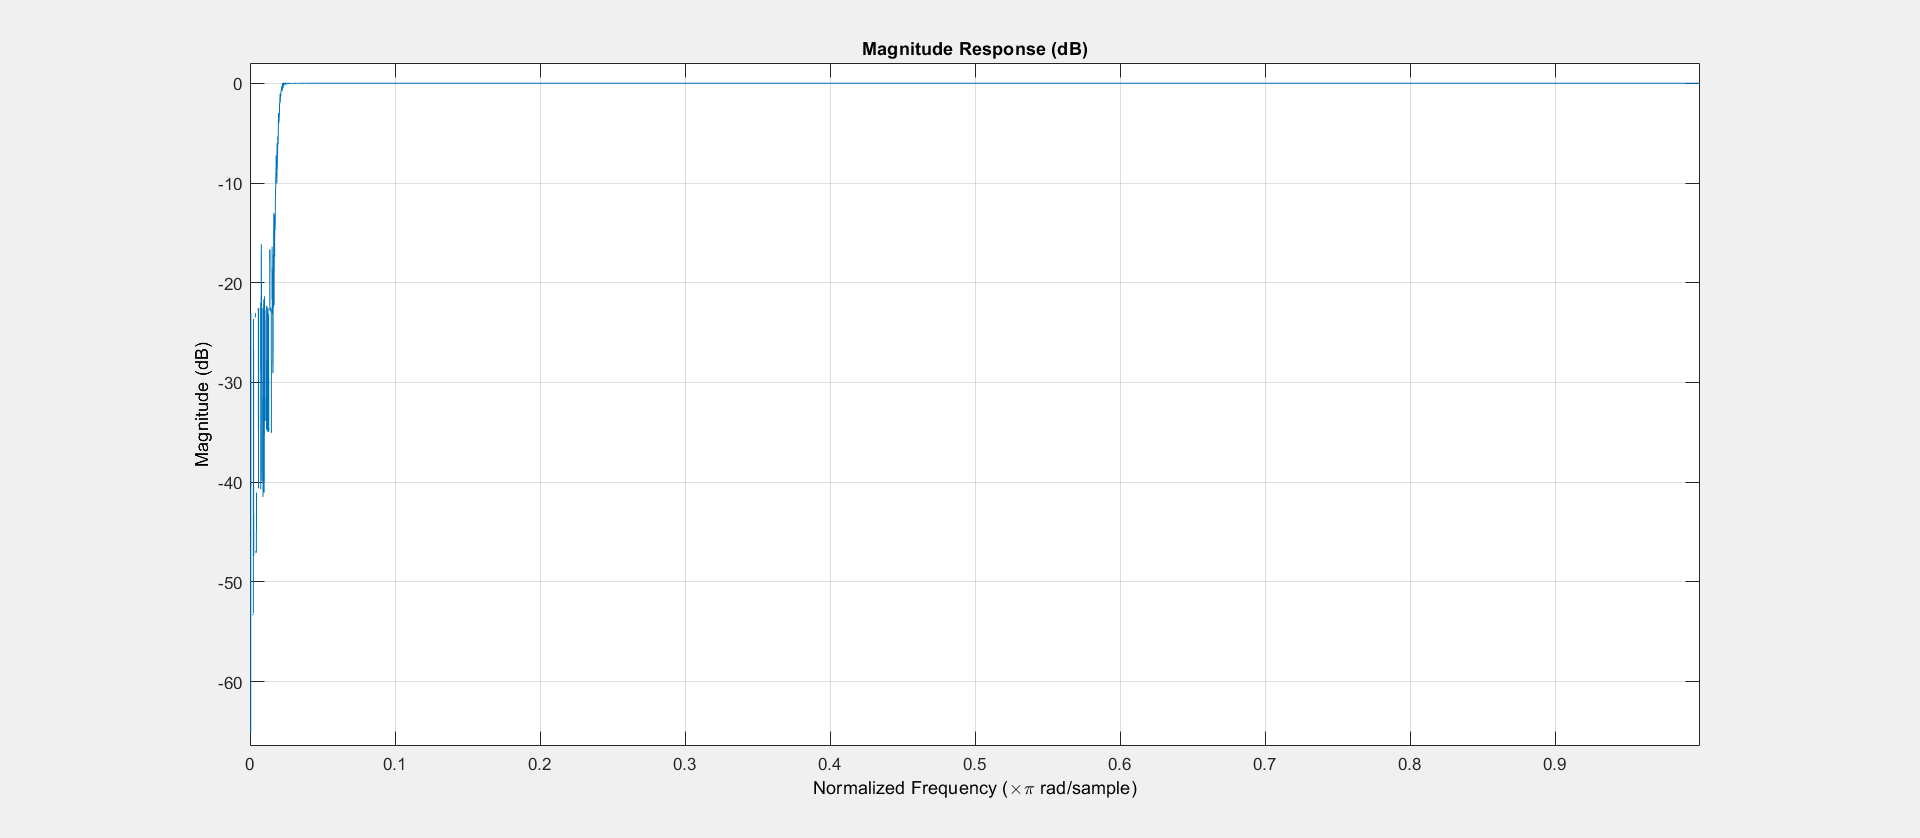

[hpb,hpa]=butter(10,5/250,'high');
fvtool(hpb,hpa)

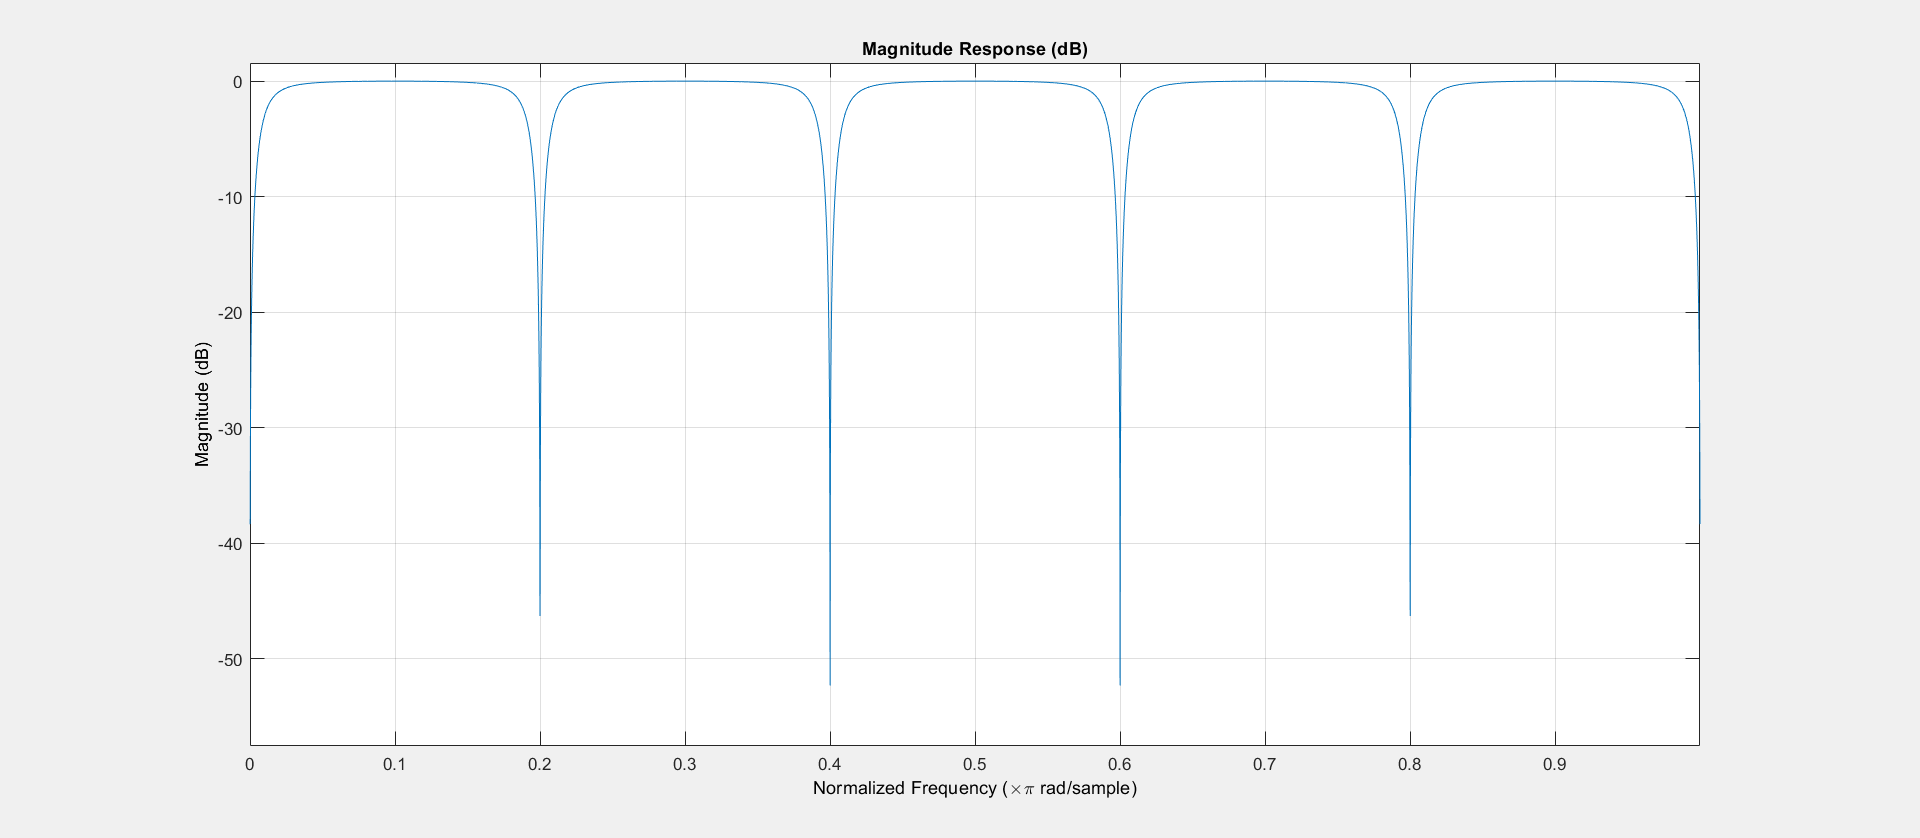

[combb,comba]=iircomb(10,5/250);
fvtool(combb,comba)

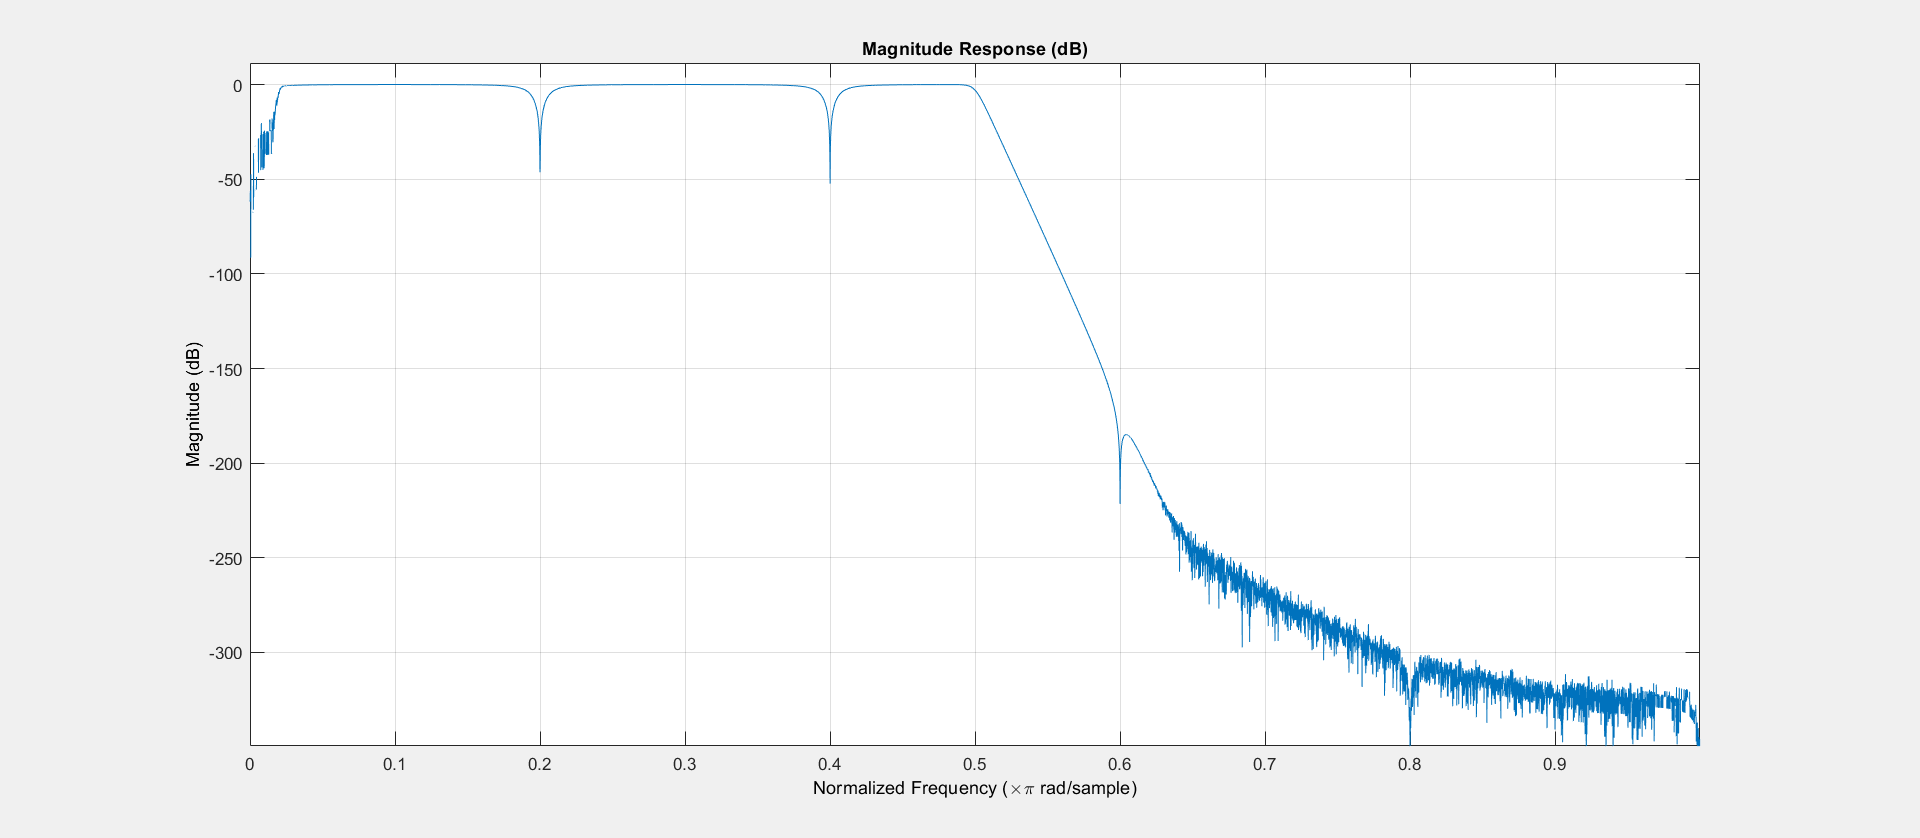

H1=dfilt.df2t(lpb,lpa);
H2=dfilt.df2t(hpb,hpa);
H3=dfilt.df2t(combb,comba);
fvtool(dfilt.cascade(H1,H2,H3));

% Filtering methods using IIR filters

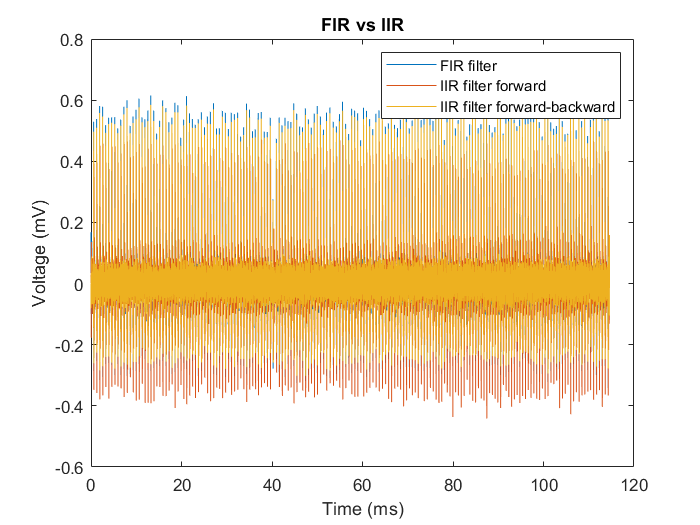

ECG_filter=filter(lpb,lpa,nECG);
ECG_filter=filter(hpb,hpa,ECG_filter);
ECG_filter=filter(combb,comba,ECG_filter);

ECG_filtfilt=filtfilt(lpb,lpa,nECG);
ECG_filtfilt=filtfilt(hpb,hpa,ECG_filtfilt);
ECG_filtfilt=filtfilt(combb,comba,ECG_filtfilt);

t=(0:length(nECG)-1)/500;
plot(t,combined_filtered_ecg1,t,ECG_filter,t,ECG_filtfilt);
xlabel('Time (ms)');
ylabel('Voltage (mV)');
legend('FIR filter','IIR filter forward','IIR filter forward-backward')
title('FIR vs IIR');

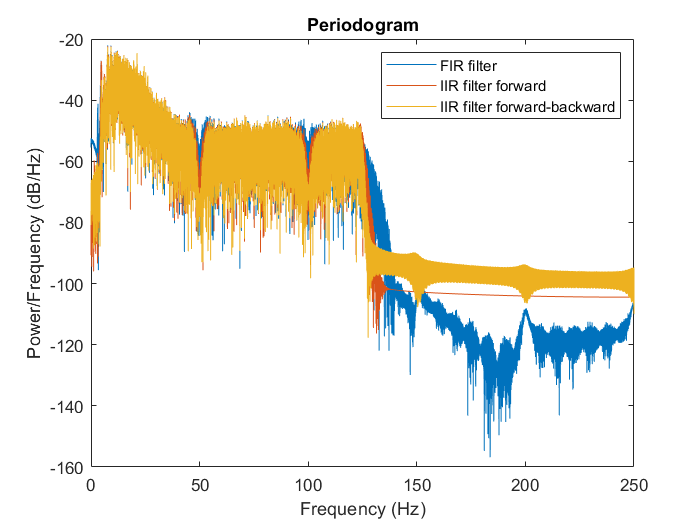

[Pxx1, Freq1] = periodogram(combined_filtered_ecg1, [], [], 500);
[Pxx2, Freq2] = periodogram(ECG_filter, [], [], 500);
[Pxx3, Freq3] = periodogram(ECG_filtfilt, [], [], 500);
figure;
plot(Freq1, 10*log10(Pxx1), Freq2, 10*log10(Pxx2), Freq3, 10*log10(Pxx3));
xlabel('Frequency (Hz)');
ylabel('Power/Frequency (dB/Hz)');
legend('FIR filter','IIR filter forward','IIR filter forward-backward')
title('Periodogram');